# Q1. Transfer Learning - Image Classification *(50 points)*

## 1. Pretrained network (3)

###     1.1. Import GoogLeNet (1)

net = googlenet

net =   DAGNetwork - 속성 있음:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


###     1.2. What is the input image size of GoogLeNet? (2)

      Enter your code to ouput the input image size of GoogLeNet.

layers = net.Layers

layers =   다음 계층을 포함한 144×1 Layer 배열:

     1   'data'                           영상 입력              224×224×3 영상 (정규화: 'zerocenter')
     2   'conv1-7x7_s2'                   2차원 컨벌루션          64개 7×7×3 컨벌루션(스트라이드: [2  2], 채우기: [3  3  3  3])
     3   'conv1-relu_7x7'                 ReLU                  ReLU
     4   'pool1-3x3_s2'                   2차원 최댓값 풀링       3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  1  0  1])
     5   'pool1-norm1'                    교차 채널 정규화        교차 채널 정규화 (요소당 채널 5개)
     6   'conv2-3x3_reduce'               2차원 컨벌루션          64개 1×1×64 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     7   'conv2-relu_3x3_reduce'          ReLU                  ReLU
     8   'conv2-3x3'                      2차원 컨벌루션          192개 3×3×64 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
     9   'conv2-relu_3x3'                 ReLU                  ReLU
    10   'conv2-norm2'                    교차 채널 정규화        교차 채널 정규

layers_input = layers(1)

layers_input =   ImageInputLayer - 속성 있음:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   하이퍼파라미터
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


layers_output = layers(end)

layers_output =   ClassificationOutputLayer - 속성 있음:

            Name: 'output'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   하이퍼파라미터
    LossFunction: 'crossentropyex'


input_size = layers_input.InputSize

input_size =    224   224     3


classes = layers_output.Classes

classes = 1000×1 categorical 배열
     tench 
     goldfish 
     great white shark 
     tiger shark 
     hammerhead 
     electric ray 
     stingray 
     cock 
     hen 
     ostrich 
     brambling 
     goldfinch 
     house finch 
     junco 
     indigo bunting 
     robin 
     bulbul 
     jay 
     magpie 
     chickadee 
     water ouzel 
     kite 
     bald eagle 
     vulture 
     great grey owl 
     European fire salamander 
     common newt 
     eft 
     spotted salamander 
     axolotl 


## 2. Importing dataset (7)

###     2.1. Create an image datastore (5)

      Create an image datastore which references the folder of the dataset.

imageDS = imageDatastore("Q1_data/","IncludeSubfolders",true,...
    "LabelSource","foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../Documents/MATLAB/인공지능/week8_midterm/Q1_data/cat/1.jpeg';
                              ' .../Documents/MATLAB/인공지능/week8_midterm/Q1_data/cat/10.jpeg';
                              ' .../Documents/MATLAB/인공지능/week8_midterm/Q1_data/cat/100.jpeg'
                               ... and 1597 more
                              }
                     Folders: {
                              ' .../jeongseong-yun/Documents/MATLAB/인공지능/week8_midterm/Q1_data'
                              }
                      Labels: [cat; cat; cat ... and 1597 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDa

% imageDS = 

###     2.2 What ouput classes does the dataset contain? (2)

      Output the classes of the dataset.

categories(imageDS.Labels)

ans = 8×1 cell 배열
    {'cat'     }
    {'chicken' }
    {'cow'     }
    {'dog'     }
    {'elephant'}
    {'horse'   }
    {'sheep'   }
    {'squirrel'}


*           View a sample image of each class*

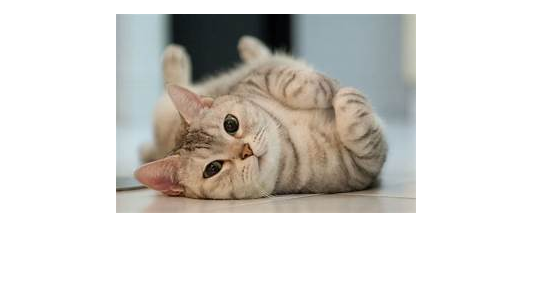

    %-------------- DO NOT modify this code--------------
    selectedClass="cat";
    classIdx = contains(imageDS.Files,selectedClass);
    countClass = sum(classIdx);
    randNum = randi([1,countClass],1);
    classRowNum = find(classIdx);
    classRandIm = readimage(imageDS, classRowNum(1)+randNum-1);
    imshow(classRandIm)

    %----------------------------------------------------

## 3. Preparing Data (10)

###     3.1. Split dataset (3)

      Split the dataset into train(0.8) and test data(0.2). **DO NOT include validation data.**

[TrainImages, TestImages] = splitEachLabel(imageDS, 0.8)

TrainImages =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../Documents/MATLAB/인공지능/week8_midterm/Q1_data/cat/1.jpeg';
                              ' .../Documents/MATLAB/인공지능/week8_midterm/Q1_data/cat/10.jpeg';
                              ' .../Documents/MATLAB/인공지능/week8_midterm/Q1_data/cat/100.jpeg'
                               ... and 1277 more
                              }
                     Folders: {
                              ' .../jeongseong-yun/Documents/MATLAB/인공지능/week8_midterm/Q1_data'
                              }
                      Labels: [cat; cat; cat ... and 1277 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @re

TestImages =   ImageDatastore - 속성 있음:

                       Files: {
                              ' .../Documents/MATLAB/인공지능/week8_midterm/Q1_data/cat/42.jpeg';
                              ' .../Documents/MATLAB/인공지능/week8_midterm/Q1_data/cat/43.jpeg';
                              ' .../Documents/MATLAB/인공지능/week8_midterm/Q1_data/cat/44.jpeg'
                               ... and 317 more
                              }
                     Folders: {
                              ' .../jeongseong-yun/Documents/MATLAB/인공지능/week8_midterm/Q1_data'
                              }
                      Labels: [cat; cat; cat ... and 317 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readD

###     3.2. Augment data (7)

      Augment the data for transfer learning. If you have a syntax error in 5.2., see the '`augmentedImageDatastore`' documentation.

TrainData = augmentedImageDatastore([224,224],TrainImages, ColorPreprocessing="gray2rgb")

TrainData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 1280
                       Files: {1280×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


TestData = augmentedImageDatastore([224,224],TestImages,ColorPreprocessing="gray2rgb")

TestData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 320
                       Files: {320×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## 4. Modifying Network (15)

Modify appropriate layers of GoogLeNet using **'Deep Network Designer'** app so that the network works for your dataset. If you complete the modification of the network, in the App, use **'Export network to workspace'** to export the network to your workspace. Your new network will be saved as `'lgraph_1'` in the workspace.

**Be sure to include your network(**`'lgraph_1'`**) into the zip file, when you submit your answer.**

## 5. Training Network (5)

Create appropriate training options to obtain good prediction accuracy for the test data.

###     5.1. Create training options (3)

      The training options you **SHOULD KEEP** are as follows. The rest of training options are tunerable.

- Max epochs: 10

- Display training progress

opts = trainingOptions("sgdm", "InitialLearnRate",0.001,"MaxEpochs",10,"Plots","training-progress")

opts =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 10
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
              

###     5.2. Train Network (2)

      Train network. You might see a sytax error when starting the training, and be required to add an optional argument in 3.2.

newnet = trainNetwork(TrainData, lgraph_1, opts)

'lgraph_1'은(는) 인식할 수 없는 함수 또는 변수입니다.

## 6. Evaluating network (10)

Evaluate the network by classifying the test data, calculating the classification accuracy and displaying a confusion chart.

###     6.1. Predict the class of the test data (3)

pred = classify(newnet, TestData)

###     6.2. Calculate the prediction accuracy (5)

GT = TestImages.Labels
Acc = nnz(pred == GT)/numel(GT)

###     6.3. Display a confusion chart (2)

confusionchart(GT,pred)